** The cart and pole system**

Consider the cart-and-pole system here depicted:

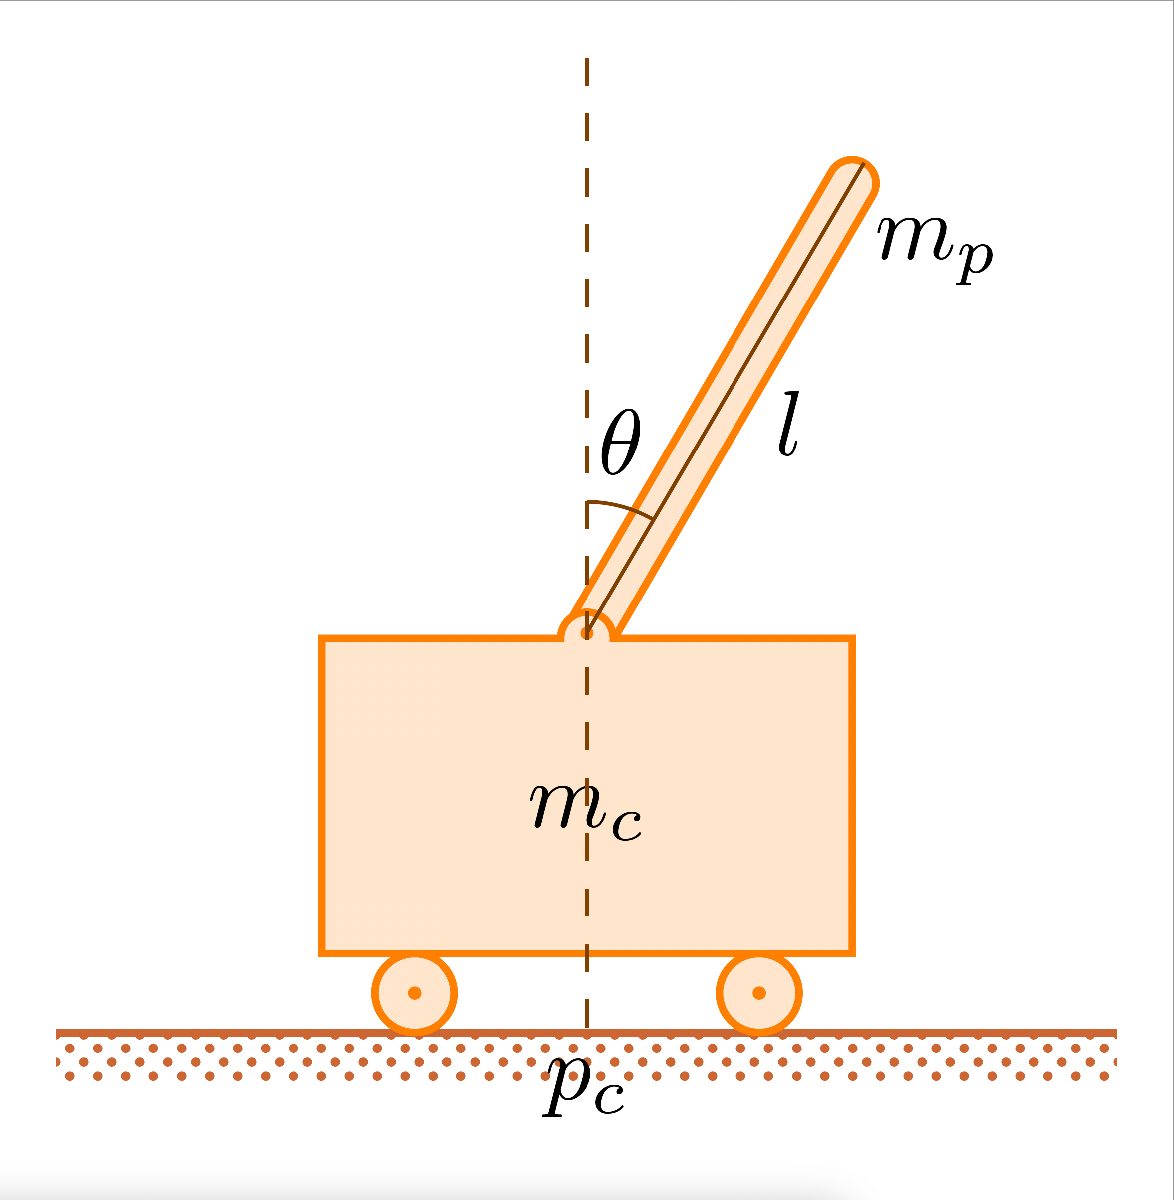

whose dynamics follows the following equations:


$$\ddot{\theta}=\frac{g \sin(\theta)\,+\,\cos(\theta) \left[ \frac{-F\,-\,m_p\,l\,\dot{\theta}^2 \sin \left(\theta\right)}{m_c\,+\,m_p}\right]-\frac{\mu_p\dot{\theta}}{m_p\,l}}{l\,\left[\frac{4}{3}-\frac{m_p\,cos^2\left(\theta\right)}{m_c\,+\,m_p}\right]}$$
   


$$(*)$$



$$  \ddot{p}_c=\frac{F\,+\,m_p\,l\,\left[\dot{\theta}^2\,\sin\left(\theta\right)\,-\,\ddot{\theta}\,\cos(\theta)\right]}{m_c\,+\,m_p}$$


where $g = 9.8\,\text{m/sec}$ is the gravitational acceleration, $m_c = 1\,\text{kg}$ is the cart mass, $m_p = 0.1\,\text{kg}$ is the pole mass, $l = 0.5\,\text{m}$ is the half-pole length, $\mu_p = 0.000002$ is the pole on cart friction coefficient, and $F:|F|\leq 10\,\text{N}$ is the force applied to cart's center of mass.

1. Clearly define the state vector $x$ and the control input vector $u$. Define also the domains to which they belong, $X$ and $U$respectively.

% Answer: Defining the state as following:

Defining the state vector as follow

$x= [x_1 \,  x_ 2 \, x_3 \, x_4]^T$where


$$x_1= \theta$$



$$x_2= {d{\theta}\over dt}$$



$$x_3= pc$$



$$x_4= {d{pc}\over dt}$$


$x1 \in 
[{{-\pi}\over2}, {\pi\over 2}]$ that corresponds to the angle supposing that the pole is free to rotate for 90° on the right and 90° on the left

$x_2 \in  \mathbb{R}$ that's the angular velocity of the pole

$x3 \in  \mathbb{R}$, the cart is free to move along x axis parallel to the ground

$x4 \in  \mathbb{R}$, that is the velocity of the cart, that for example if a constant force is applied, it will move increasing his velocity

this imply that the domain of the state vector is the cartesian product of the previous.

The input vector it will be the force applied to the cart, that can be applied from the left and from the right so 


$$u=F$$


$u \in $ {-10,10}

2. Compute the equilibrium state $$\bar{x}$$ when the control input $$\bar{u}$$ is set equal to $$0$$.

% Answer: 
clear all 
close all
clc                 % cleaning the workspace
sympref('default')

ans = struct with fields:
           FourierParameters: [1    -1]
           HeavisideAtOrigin: 1/2
            AbbreviateOutput: 1
               TypesetOutput: 1
         FloatingPointOutput: 0
      PolynomialDisplayStyle: 'default'
    MatrixWithSquareBrackets: 0


syms theta dt pc dpc
format short
u=0

u = 0

g=9.8 

g = 9.8000

mc=1

mc = 1

mp=0.1

mp = 0.1000

l=0.5

l = 0.5000

mu_p=0.000002

mu_p = 2.0000e-06

syms f1(pc,dpc , theta , dt ) f2(pc,dpc , theta , dt)

f1(theta, dt,pc, dpc)=(((g*sin(theta)+cos(theta)*(((-u-mp*l*(dt^2)*sin(theta))/(mc+mp)))-(mu_p*dt)/(mp*l)))/(l*(4/3-(mp*(cos(theta)^2)/(mc+mp)))))

$$f1(theta, dt, pc, dpc) = \frac{\frac{\cos\left(\theta \right)\,\sin\left(\theta \right)\,{\mathrm{dt}}^{2}}{22}+\frac{23611832414348225\,\mathrm{dt}}{590295810358705651712}-\frac{49\,\sin\left(\theta \right)}{5}}{\frac{{\cos\left(\theta \right)}^{2}}{22}-\frac{2}{3}}$$


f2(theta, dt, pc , dpc)=(u+mp*l*(((dt)^2)*sin(theta)-(f1(pc, dpc, theta, dt))*cos(theta)))/(mc+mp)

$$f2(theta, dt, pc, dpc) = \frac{{\mathrm{dt}}^{2}\,\sin\left(\theta \right)}{22}-\frac{\cos\left(\theta \right)\,\left(\frac{\cos\left(\mathrm{pc}\right)\,\sin\left(\mathrm{pc}\right)\,{\mathrm{dpc}}^{2}}{22}+\frac{23611832414348225\,\mathrm{dpc}}{590295810358705651712}-\frac{49\,\sin\left(\mathrm{pc}\right)}{5}\right)}{22\,\left(\frac{{\cos\left(\mathrm{pc}\right)}^{2}}{22}-\frac{2}{3}\right)}$$

The equilibrium state $\bar x$  is defining  such that $0= f(\bar x, \bar u)= \dot x$, so the system to consider is:


$$\begin{array}{l}
\\
0=\frac{\mathrm{d}}{\mathrm{d}t}\textrm{pc}
\end{array}$$



$$\begin{array}{l}
\\
0=\frac{\mathrm{d}}{\mathrm{d}t}\theta 
\end{array}$$



$$\ddot \theta=0=\frac{g \sin(\theta)\,+\,\cos(\theta) \left[ \frac{-F\,-\,m_p\,l\,\dot{\theta}^2 \sin \left(\theta\right)}{m_c\,+\,m_p}\right]-\frac{\mu_p\dot{\theta}}{m_p\,l}}{l\,\left[\frac{4}{3}-\frac{m_p\,cos^2\left(\theta\right)}{m_c\,+\,m_p}\right]}$$



$$ \ddot pc= 0=\frac{F\,+\,m_p\,l\,\left[\dot{\theta}^2\,\sin\left(\theta\right)\,-\,\ddot{\theta}\,\cos(\theta)\right]}{m_c\,+\,m_p}$$


So the sys is the following:

disp(f1(pc, 0,theta, 0)) %f1

$$-\frac{49\,\sin\left(\mathrm{pc}\right)}{5\,\left(\frac{{\cos\left(\mathrm{pc}\right)}^{2}}{22}-\frac{2}{3}\right)}$$

disp(f2(pc, 0, theta , 0))%f2

$$\frac{49\,\cos\left(\mathrm{pc}\right)\,\sin\left(\theta \right)}{110\,\left(\frac{{\cos\left(\theta \right)}^{2}}{22}-\frac{2}{3}\right)}$$



theta=solve(f1(pc, 0,theta, 0), theta)

 
theta =
 
Empty sym: 0-by-1
 


It is easy to identify that there is one equilibrium state,  given by the state vector:


$$\bar x_1 = [0\,  0\, 0 \, 0]$$


Now it is time to evaluate which type of equilibrium state it is, so considering an constant input and equal to zero, the evaluation will be performed starting from an intial condition so close to the equilibrium state and studying how the system will evolve. Before this lets evaluate the system at equilibrium state to show that the condition $0= f(\bar x, \bar u)= \dot x$ holds,and then evaluate which type of equilibrium it is.

clc
clear all



g=9.8

g = 9.8000

 %force applied
mp=0.1 %kart pole

mp = 0.1000

mc=1% cart weight

mc = 1

l=0.5 %pale length

l = 0.5000

mu_c=0%friction constant between cart and the ground

mu_c = 0

mu_p=0.000002%friction constant between pole and cart

mu_p = 2.0000e-06

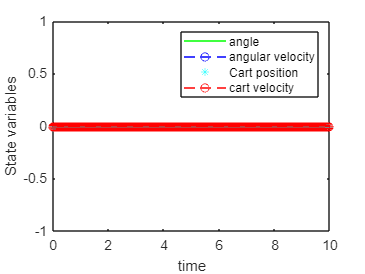

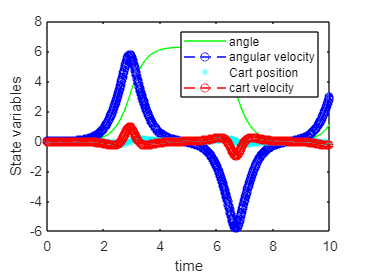

theta=[deg2rad(0) deg2rad(0.1)];% try with other values present in theta domain

InCon=[theta(1) 0 0 0;
       theta(2) 0 0 0;
       ];
 %Initial condition, respectively position,velocity, angle , angular velocity

t_span= 0:0.01:10;
F=0;

for i=1:2

[t results]= ode45(@(t, y)solving1(t, y,g,F,mp,mc,l,mu_p), t_span, InCon(i,:));
figure
plot(t,results(:,1),'g')
hold on
plot(t,results(:,2),'b--o')
plot(t,results(:,3),'c*')
plot(t,results(:,4),'r--o')
legend('angle','angular velocity','Cart position','cart velocity')%'Position cart','velocity','angle','angular velocity','best'
ylabel('State variables')
xlabel('time')
end

From the previous plots, in particular from the second  one, the initial condition is changed to $\theta_i=0.01$ degree  it can be stated that the $\bar x_1$ is unstable equilibrium state by definition.

3. Given the sequence of control inputs$ $$\left[u^{(0)},\,u^{(1)},\cdots,u^{(1001)}\right]$$$ simulate the behaviour of the non linear system $$(*)$$

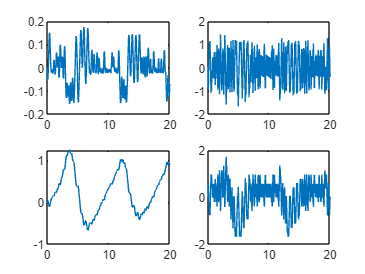

%clear all
%close all
%clc


% constants definition
g = 9.8; % gravitational acceleration
mc = 1;   % cart mass [kg]
l = 0.5; % half-pole length [m]
mp = 0.1; % pole mass [kg]
mup = 0.000002; % pole friction coefficient


theta0 = 0;
x0 = 0; 
dot_x0 = 0;
dot_theta0 = 0;

t2=0;
conds=[theta0, dot_theta0, x0, dot_x0];
X_nl = conds';

load U
N=length(U);

u = U;
timestep = 0.02;

for i = 1:N
    t1 = t2;
    t2 = t2+timestep;
    time = [t1, t2];
    [t,state] = ode45(@(t,x)solving1(t, x, g, u(i), mp, l, mc, mup), time, conds);
    tp = find(t == t2);
    conds = state(tp,:);
    X_nl = [X_nl, conds'];
end

tfin = timestep*length(X_nl)-timestep;
figure()
subplot(2,2,1)
plot(0:timestep:tfin,X_nl(1,:))
subplot(2,2,2)
plot(0:timestep:tfin,X_nl(2,:))
subplot(2,2,3)
plot(0:timestep:tfin,X_nl(3,:))
subplot(2,2,4)
plot(0:timestep:tfin,X_nl(4,:))

4. Given the non linear system $(\ast )$ linearize it around the equilibrium point computed in the point 2 and simulate the behaviour of the linear systems given the same sequence of control inputs of point 3.

% Answer: (Provide the code, an animation of the system the plots of the state evolution)
clear all 
close all
clc  
load U ;
sympref('default')

ans = struct with fields:
           FourierParameters: [1    -1]
           HeavisideAtOrigin: 1/2
            AbbreviateOutput: 1
               TypesetOutput: 1
         FloatingPointOutput: 0
      PolynomialDisplayStyle: 'default'
    MatrixWithSquareBrackets: 0


syms theta dt pc dpc
format short
syms u g mc mp l mu_p
load('U.mat');
syms f1(theta, dt, pc , dpc) f2(theta, dt, pc , dpc)


f1(theta, dt, pc , dpc)=(((g*sin(theta)+cos(theta)*(((-u-mp*l*(dt^2)*sin(theta))/(mc+mp)))-(mu_p*dt)/(mp*l)))/(l*(4/3-(mp*(cos(theta)^2)/(mc+mp)))));

f2(theta, dt, pc , dpc)=(u+mp*l*(((dt)^2)*sin(theta)-(f1(pc, dpc, theta, dt))*cos(theta)))/(mc+mp);
f_x=jacobian([dt;f1;dpc;f2],[theta;dt;pc;dpc]);
g_x=jacobian([dt;f1;dpc;f2],[u]);

%evaluating A matrix after linearization

pc=0;
dpc=0;
theta=0;
dt=0

dt = 0

A1=eval(f_x)

$$A1 = \begin{array}{l} \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ -\frac{g}{l\,\sigma_{1}} & \frac{\mu_{p}}{l^{2}\,\mathrm{mp}\,\sigma_{1}} & 0 & 0\\ 0 & 0 & 0 & 1\\ 0 & 0 & \frac{g\,\mathrm{mp}}{\left(\mathrm{mc}+\mathrm{mp}\right)\,\sigma_{1}} & -\frac{\mu_{p}}{l\,\left(\mathrm{mc}+\mathrm{mp}\right)\,\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\mathrm{mp}}{\mathrm{mc}+\mathrm{mp}}-\frac{4}{3} \end{array}$$

B1=eval(g_x)

$$B1 = \left(\begin{array}{c} 0\\ \frac{1}{l\,\left(\mathrm{mc}+\mathrm{mp}\right)\,\left(\frac{\mathrm{mp}}{\mathrm{mc}+\mathrm{mp}}-\frac{4}{3}\right)}\\ 0\\ -\frac{\frac{\mathrm{mp}}{\left(\mathrm{mc}+\mathrm{mp}\right)\,\left(\frac{\mathrm{mp}}{\mathrm{mc}+\mathrm{mp}}-\frac{4}{3}\right)}-1}{\mathrm{mc}+\mathrm{mp}} \end{array}\right)$$




n=size(A1)

n =      4     4


value=[g, mp, mc, mu_p, l];
A1=double(subs(A1,value,[9.8 0.1 1 0.000002 0.5]))

A1 =          0    1.0000         0         0
   15.7756   -0.0001         0         0
         0         0         0    1.0000
         0         0   -0.7171    0.0000



B1=double(subs(B1,value,[9.8 0.1 1 0.000002 0.5]))

B1 =          0
   -1.4634
         0
    0.9756


sys=ss(A1,B1,eye(n),0)

sys =
 
  A = 
               x1          x2          x3          x4
   x1           0           1           0           0
   x2       15.78  -6.439e-05           0           0
   x3           0           0           0           1
   x4           0           0     -0.7171   2.927e-06
 
  B = 
           u1
   x1       0
   x2  -1.463
   x3       0
   x4  0.9756
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
 
Continuous-time state-space model.


sysTD=c2d(sys, 0.02)

sysTD =
 
  A = 
             x1        x2        x3        x4
   x1     1.003   0.02002         0         0
   x2    0.3158     1.003         0         0
   x3         0         0    0.9999      0.02
   x4         0         0  -0.01434    0.9999
 
  B = 
               u1
   x1  -0.0002928
   x2     -0.0293
   x3   0.0001951
   x4     0.01951
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
 
Sample time: 0.02 seconds
Discrete-time state-space model.



t_span= 0:0.02:20;

nTime     = length(t_span);
x=[0 ;0; 0 ;0]

x =      0
     0
     0
     0


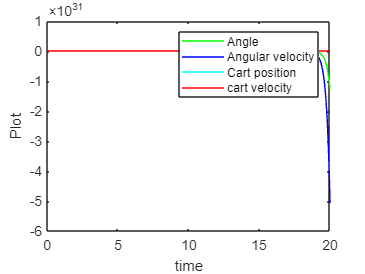



y(1, :) = x;
for i=1:nTime-1

y(i+1,:)=linearize(x,sysTD.A,sysTD.B,U(i));
x=y(i+1,:)';
end

figure;
plot(t_span,y(:,1),'g');
hold on
plot(t_span,y(:,2),'b');

plot(t_span,y(:,3),'c');

plot(t_span,y(:,4),'r');
legend('Angle','Angular velocity','Cart position','cart velocity');%'Position cart','velocity','angle','angular velocity','best'
ylabel('Plot');
xlabel('time');

5. Comment the results obtained in point 3 and 4. Do you observe any difference?

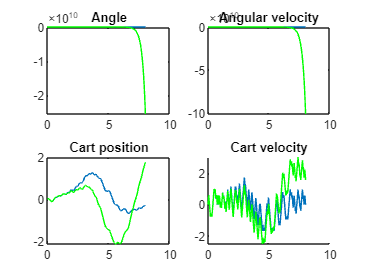


% Answer: (Arguing the answer)
g = 9.8; % gravitational acceleration
mc = 1;   % cart mass [kg]
l = 0.5; % half-pole length [m]
mp = 0.1; % pole mass [kg]
mup = 0.000002; % pole friction coefficient

theta0 = 0;
x0 = 0; 
dot_x0 = 0;
dot_theta0 = 0;

t2=0;
conds=[theta0, dot_theta0, x0, dot_x0];
X_nl = conds';

load U
N=400;

u = U;
timestep = 0.02;

for i = 1:N
    t1 = t2;
    t2 = t2+timestep;
    time = [t1, t2];
    [t,state] = ode45(@(t,x)solving1(t, x, g, u(i), mp, l, mc, mup), time, conds);
    tp = find(t == t2);
    conds = state(tp,:);
    X_nl = [X_nl, conds'];
end
tfin = timestep*length(X_nl)-timestep;





figure()
subplot(2,2,1)
plot(0:timestep:tfin,X_nl(1,:))
hold on
plot(0:timestep:tfin,y(1:N+1,1),'g');
title('Angle');
subplot(2,2,2)
plot(0:timestep:tfin,X_nl(2,:))
hold on
plot(0:timestep:tfin,y(1:N+1,2),'g');
title('Angular velocity');
subplot(2,2,3)
plot(0:timestep:tfin,X_nl(3,:))
hold on
plot(0:timestep:tfin,y(1:N+1,3),'g');
title('Cart position');
subplot(2,2,4)
hold on
plot(0:timestep:tfin,X_nl(4,:))
plot(0:timestep:tfin,y(1:N+1,4),'g');
title('Cart velocity');

In blue the non linear system and in green the linearized around the unstable equilibrium point